# Floating point numbers

## Special values

a1 = 1/0

a1 = Inf

a2 = -1/0

a2 = -Inf

a3 = 0/0

a3 = NaN

a4 = nan(1,1)

a4 = NaN

a5 = Inf/NaN

a5 = NaN

a6 = Inf/0

a6 = Inf

o = eps(0)

o = 4.9000e-324

## Precision

Precision is not constant throughout floating point numbers' range. As the numbers get larger, the precision gets larger as well. 		

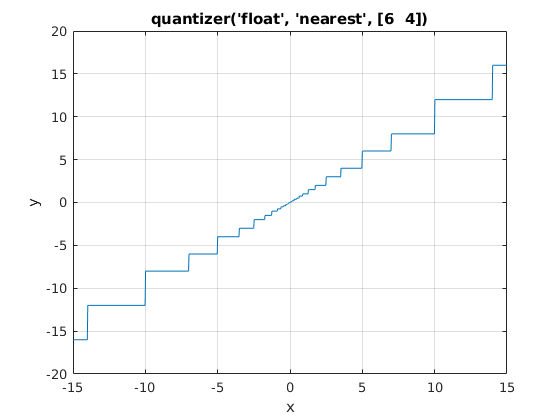

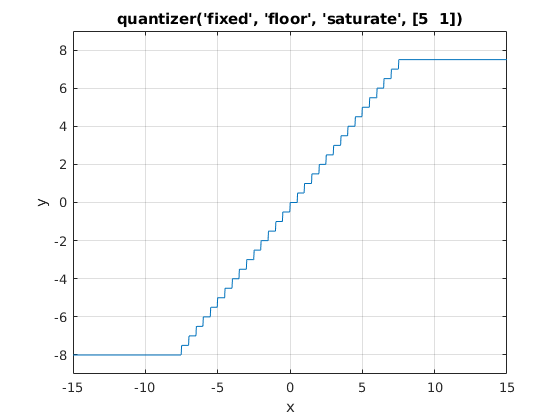

x = linspace(-15, 15, 1000);

% Fixed point
q = quantizer('fixed',[5 1], 'Overflowmode', 'saturate'); % [wordlength fractionlength] 
y2 = quantize(q, x);
plot(x, y2); title(tostring(q)); xlabel('x'); ylabel('y')
grid on
axis([ -15 15 -9 9 ])

% Floating point 
q = quantizer([6 4],'float', 'Roundmode', 'nearest'); % [wordlength exponentlength] 
y1 = quantize(q, x);
plot(x, y1); title(tostring(q)); xlabel('x'); ylabel('y')
grid on

`eps(x)` returns the positive distance from `abs(x)` to the next larger in magnitude floating point number of the same precision. 

e1 = eps(single(1))

e1 = single
1.1921e-07

e2 = eps(single(1e1))

e2 = single
9.5367e-07

e3 = eps(single(1e10))

e3 = single
1024

format bank
f1 = single(1e10) +  single(1300)

f1 = single
 10000001024.00


When calculations involve large and small numbers at the same time, the loss of precision affects the small number and the result.

format short
g1 = (2^53 + 1) - 2^53

g1 = 0

x = 0;
f3 = tan(x) - sin(x)/cos(x)

f3 = 0

x = 1;
f2 = tan(x) - sin(x)/cos(x)

f2 = 2.2204e-16

More examples

%% Multiplication

a = single(0.01);
b = single(0.01);

C = a * b;

C_log = exp ( log (a) + log (b) );

err_mul = C - C_log

err_mul = single
7.2760e-12


%% MAC

A = (randn(1,100) * 100000);
B = (randn(1,100) * 1);

C = single(A) .* single(B) ;

mac_single = sum( C )

mac_single = single
1.2859e+06


mac_sort  = sum( sort(C) )

mac_sort = single
1.2859e+06


mac_double  = sum ( (A .* B) )

mac_double = 1.2859e+06


err_mac      = (mac_double - double(mac_single))

err_mac = -0.0424

err_mac_sort = (mac_double - double(mac_sort))

err_mac_sort = -0.0424